clc;
clear;


% Domain of X
x0 = 0;
xL = 1;
L = xL; % Length
%f = 4*x^2 - 2*x -4; % Source term
f = -1;
e = 4;
% numerical values for a, c, and h
a = 3;

% Get the handle of the command window
commandwindow;

prompt_x0 = 'Enter the type of boundary condition at x0 (1. Fixed, 2. Roller/ Pin, 3. Free end): ';
type_x0 = input(prompt_x0);

switch type_x0
    case 1
        y0 = 0;  % Displacement at x0 is zero (Fixed end)
        theta0 = 0;  % Rotation at x0 is zero
    case 2
        y0  = 0;
        M0 = 0;  
    case 3
        % No boundary conditions to apply (Free end)
        % You can leave this section empty or add a comment like this.
    otherwise
        error('Invalid boundary condition type at x0');  % Handle invalid inputs
end


% Prompt the user to input boundary conditions at xL
prompt_xL = 'Enter the type of boundary condition at xL (1. Fixed, 2. Roller/ Pin, 3. Free end): ';
type_xL = input(prompt_xL);

switch type_xL
    case 1
        yL = 0;  % Displacement at x0 is zero (Fixed end)
        thetaL = 0;  % Rotation at x0 is zero
    case 2
        yL = 0;
        ML = 0;  
    case 3
        % No boundary conditions to apply (Free end)
        % You can leave this section empty or add a comment like this.
    otherwise
        error('Invalid boundary condition type at xL');
end


% Prompt the user to input information about loads on the beam
prompt_load = 'Is there a load or moment present on the beam? (1. Point Load, 2. Moment, 3. Both, 4. None): ';
loadResponse = input(prompt_load);

switch loadResponse
    case 1  % Point Load
        P_val = input('Enter the value of the point load: ');
        P_loc = input('Enter the location of the point load: ');
        [P_index, is_on_node] = check_location(P_loc, 'Point Load', x0, xL, e);
        if is_on_node
            disp(['Point Load is at node index: ', num2str(P_index)]);
        end

        if isempty(P_index) % Check if the index is empty
            error('In the specified location Their is No node for load.');  
        end

    case 2  % Moment
        M_val = input('Enter the value of the moment: ');
        M_loc = input('Enter the location of the moment: ');
        [M_index, is_on_node] = check_location(M_loc, 'Moment', x0, xL, e);
        if is_on_node
            disp(['Moment is at node index: ', num2str(M_index)]);
        end
        if isempty(M_index) % Check if the index is empty
            error('In the specified location Their is No node for load.');  
        end

    case 3  % Both Point Load and Moment
        P_val1 = input('Enter the value of the point load: ');
        P_loc1 = input('Enter the location of the point load: ');
        M_val1 = input('Enter the value of the moment: ');
        M_loc1 = input('Enter the location of the moment: ');
        [indices, are_on_nodes] = check_both_locations(P_loc1, M_loc1, x0, xL, e);

        P_index1 = indices(1);
        M_index1 = indices(2);

        if are_on_nodes(1)
            disp(['Point Load is at node index: ', num2str(P_index1)]);
        end
        if are_on_nodes(2)
            disp(['Moment is at node index: ', num2str(M_index1)]);
        end

        if isempty(M_index) || isempty(P_index)
            error('In the specified location Their is No node for loads.');
        end

    case 4  % None
        disp('No load or moment present, continuing with the rest of the code.');

    otherwise
        error('Invalid response. Please enter a valid option (1-4).');
end

Point Load location is on node at index 3.


Point Load is at node index: 3


**FEM Solver**

[K_global,Fv,total_DOF,X,DOF_element,DOF_node,h] = FEM_Beam_Processor(e,L,a,f);

**Post Processing**

Gv = zeros(total_DOF, 1);

if exist('P_index', 'var') && exist('P_loc', 'var') && exist('P_val', 'var')
    Gv((2*P_index)-1) = P_val;
end

if exist('M_index', 'var') && exist('M_loc', 'var') && exist('M_val', 'var')
    Gv( (2*M_index) ) = M_val;
end

if exist('P_index1', 'var') && exist('P_loc1', 'var') && exist('P_val1', 'var')
    Gv((2*P_index)-1) = P_val1;
end

if exist('M_index1', 'var') && exist('M_loc1', 'var') && exist('M_val1', 'var')
    Gv( (2*M_index1) ) = M_val1;
end

RHS = Fv + Gv;

if exist('y0', 'var') && exist('theta0', 'var')

    K_global(1,:)= [1,zeros(1, total_DOF-1)];
    K_global(2,:)= [0,1,zeros(1, total_DOF-2)];
    
    RHS(1) = y0;
    RHS(2) = theta0;
end

if exist('y0', 'var') && exist('M0', 'var')

   K_global(1,:)= [1,zeros(1, total_DOF-1)];
   RHS(1) =M0;
end

if exist('yL', 'var') && exist('thetaL', 'var')
    K_global(end-1,:) = [zeros(1, total_DOF)];
    K_global(end-1, end-1) = 1;

    K_global(end,:)= [zeros(1, total_DOF-1),1];
    RHS(end-1) = yL;
    RHS(end) = thetaL;

end

if exist('yL', 'var') && exist('ML', 'var')

    K_global(end-1,:) = [zeros(1, total_DOF)];
    K_global(end-1, end-1) = 1;

    RHS(end-1) =ML;
end


UVUV = K_global\RHS;

UV = columnVectorToMatrix(UVUV);

deflection = UV(:,1);
Slope = UV(:,2);

% myTable = table(X', deflection, Slope,'VariableNames', {'Nodal point', 'Deflection','slope'});
% disp(myTable);
% disp("-------------------------------------------------------------")

%DOF_node = 2;

[element_numbers,interpolating_functions,ranges,Bmoment1] = diff_Function(Slope,X',DOF_node,e);

% Create and display the table
Table1 = table(element_numbers, interpolating_functions, ranges, ...
          'VariableNames', {'Element Number', 'Interpolating Function', 'Range'});
%disp(Table1);
BMoment = -a*Bmoment1;


[element_numbers1,interpolating_functions1,ranges1,SF1] = diff_Function(Bmoment1',X',DOF_node,e);

% Create and display the table
Table2 = table(element_numbers1, interpolating_functions1, ranges1, ...
          'VariableNames', {'Element Number', 'Interpolating Function', 'Range'});
%disp(Table1);
SF = a*SF1;

myTable = table(X', deflection, Slope,BMoment',SF','VariableNames', {'Nodal point', 'Deflection','Slope','BM','SF'});
disp(myTable);

    Nodal point    Deflection        Slope           BM             SF    
    ___________    ___________    ___________    ___________    __________

          0         -1.036e-18     1.4456e-18     6.9754e-06    1.8601e-05
       0.25        -5.4205e-05    -5.8129e-07     2.3251e-06    1.8601e-05
        0.5        -3.6142e-19    -7.7505e-07    -2.3251e-06    1.8601e-05
       0.75        -5.4302e-05    -5.8129e-07    -6.9754e-06             0
          1                  0              0    -6.9754e-06             0



disp("-------------------------------------------------------------")

-------------------------------------------------------------


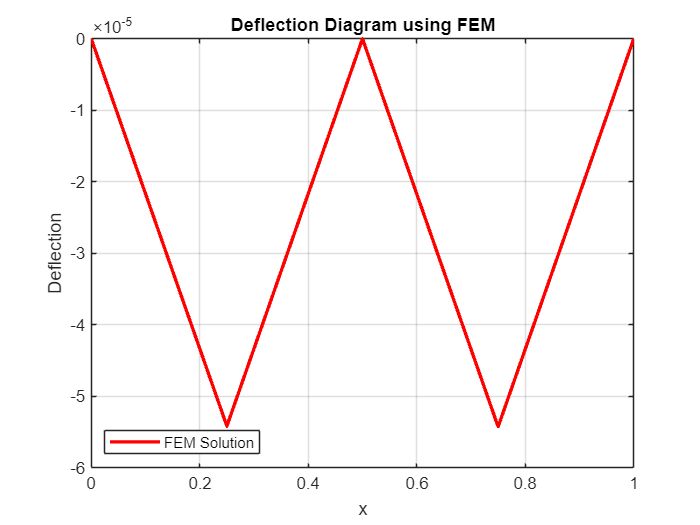


figure(1);
plot(X, deflection, "r", "LineWidth", 2, "DisplayName", "FEM Solution"); 
xlabel("x");
ylabel("Deflection");
title("Deflection Diagram using FEM");
legend('Location', 'southwest');
grid on;

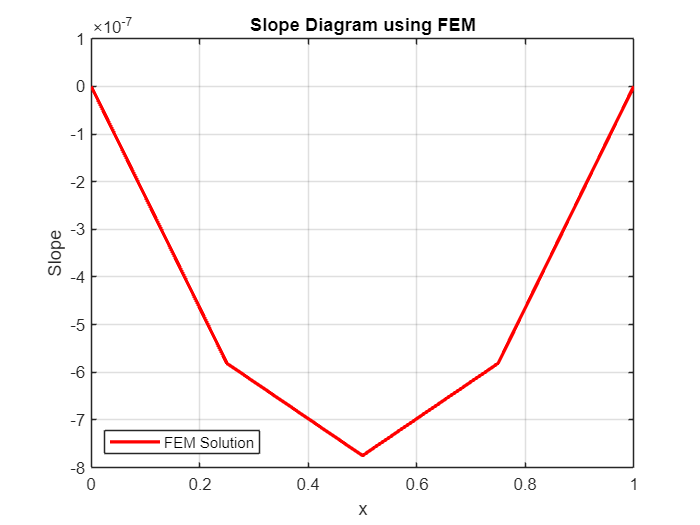


figure(2);
plot(X, Slope, "r", "LineWidth", 2, "DisplayName", "FEM Solution"); 
xlabel("x");
ylabel("Slope");
title("Slope Diagram using FEM");
legend('Location', 'southwest');
grid on;

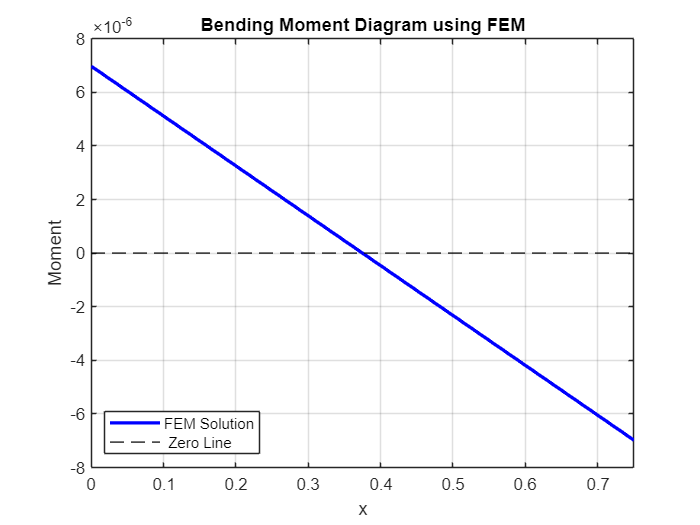


figure(3);
plot(X, BMoment, "b", "LineWidth", 2, "DisplayName", "FEM Solution"); 
xlabel("x");
ylabel("Moment");
title("Bending Moment Diagram using FEM");
legend('Location', 'southwest');
hold on; % Keeps the current plot
% Add a horizontal line at y = 0
yline(0, 'k--',"LineWidth",1, "DisplayName", " Zero Line");
grid on;
% Due to diff function last limit i don't have proper value
Last_value = xL-h;
xlim([x0 Last_value]);
hold off;

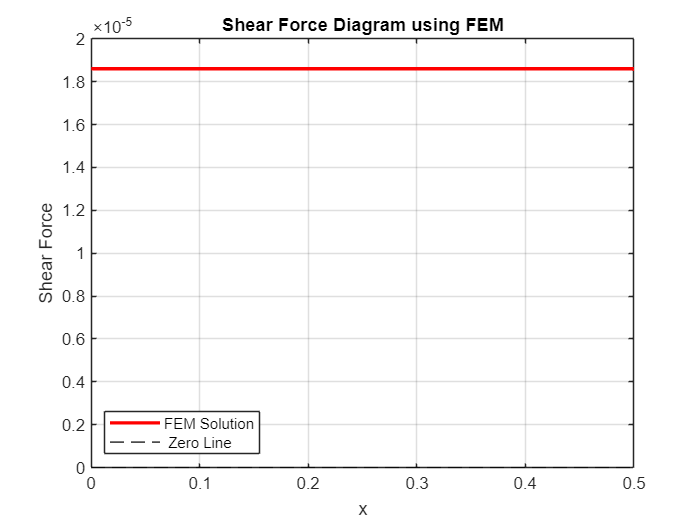


figure(4);
plot(X, SF, "r", "LineWidth", 2, "DisplayName", "FEM Solution"); 
xlabel("x");
ylabel("Shear Force");
title("Shear Force Diagram using FEM");
legend('Location', 'southwest');
hold on; % Keeps the current plot
% Add a horizontal line at y = 0
yline(0, 'k--',"LineWidth",1, "DisplayName", " Zero Line"); % Adds a red horizontal line at y = 0
grid on;
% Due to two times diff function last limit i don't have proper value
Last_value1 = Last_value-h;
xlim([x0 Last_value1]);
hold off;